# BIV Whirlpool-Galaxie Processing

## Preprocessing

Setup

dark_frame_file = "darkframe.tiff";
background_file = "background_fit.tiff";
raw_files = dir("raw/*.tiff");

addpath('code');

Load darkframe, hotpixels and background

background = im2double(imread(background_file));

hot_pixels = im2double(imread(fullfile("raw/", raw_files(1).name)));
for k = 2:numel(raw_files)
    frame = im2double(imread(fullfile("raw/", raw_files(k).name)));
    hot_pixels = hot_pixels .* frame * 10;
end

save_image(hot_pixels, "output/hot_pixels.tif");

dark_frame = im2double(imread(dark_frame_file));

Calibrate raw images by subtracting darkframe and hotpixels then save them

n = numel(raw_files);

margin_from_edge = 20;

for k = 1:n
    name = raw_files(k).name;
    img = im2double(imread(fullfile("raw/", name)));
    img_calibrated = img - dark_frame - hot_pixels;
    img_calibrated(img_calibrated < 0) = 0; % Clip negatives

    cropped = circular_crop(img_calibrated, margin_from_edge); % Crop out the edges
    save_image(cropped, fullfile("calibrated_raw/", name));
end

## Stacking

Load Calibrated

calibrated_images = {};
n = numel(raw_files);
for k = 1:n
    name = raw_files(k).name;
    img = (imread(fullfile("calibrated_raw/", name)));
   
    calibrated_images{end+1} = img;
end


Reference image

reference = calibrated_images{1};

Align images to reference by detecting stars for tracking and matching them to the reference to create the necessary transformation

aligned_images = cell(size(calibrated_images));
aligned_images{1} = reference;
h = waitbar(0, 'Aligning images...');

% Detect stars
points_fixed  = get_star_tracking_points(reference);

for k = 2:n
    moving_image = calibrated_images{k};
    
    % Detect stars
    points_moving = get_star_tracking_points(moving_image);

    [matched_points, points_moving] = match_points(points_fixed, points_moving);
    
    % Find transform
    tform = estimateGeometricTransform2D(points_moving, matched_points, 'similarity');
    
    % Warp image
    output_view = imref2d(size(reference));
    aligned = imwarp(moving_image, tform, "OutputView", output_view);
    
    aligned_images{k} = aligned;

    % Save aligned
    save_image(aligned, fullfile("aligned/", raw_files(k).name));

    waitbar(k/n, h, sprintf('Aligned %d of %d images', k, n));
end

close(h);

Stack images and convert them to double for post processing

stack_sum = zeros(size(reference), 'double');  % preallocate as double
n = numel(aligned_images);

for k = 1:n
    stack_sum = stack_sum + im2double(aligned_images{k});  % convert each frame to double
end

stack_mean = stack_sum / n;

Save

save_image(stack_mean, "output/stack.tif");

## Post Processing

Background Correction

stack_mean_crop = crop_to_match(stack_mean, background);
scaled_bg = background / 108;

img_clean = stack_mean_crop - scaled_bg;
img_clean(img_clean<0) = 0;


Enhance contrast (WIP)

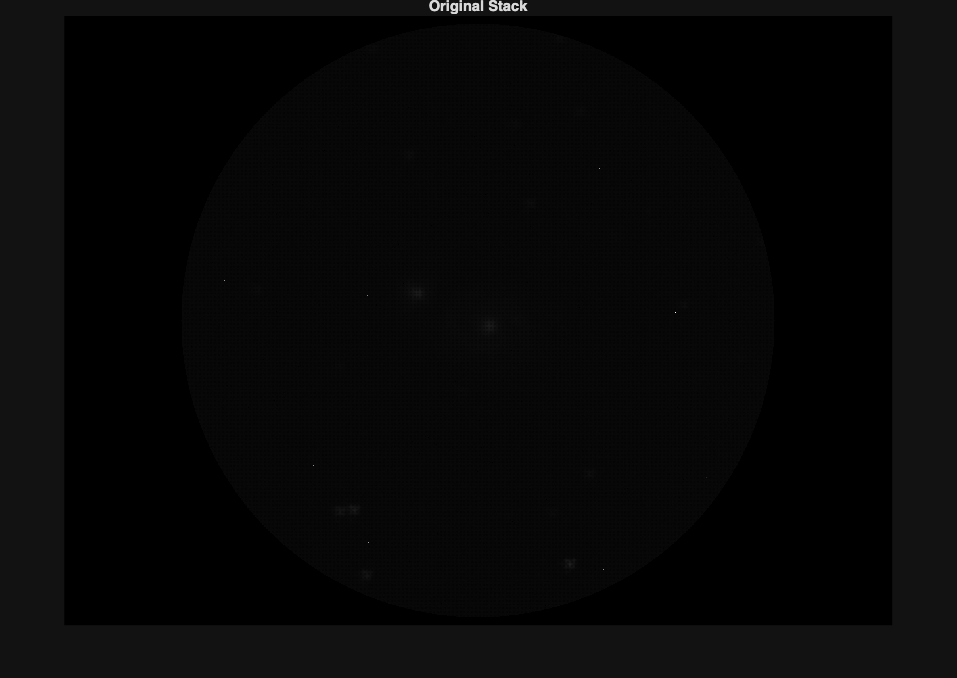

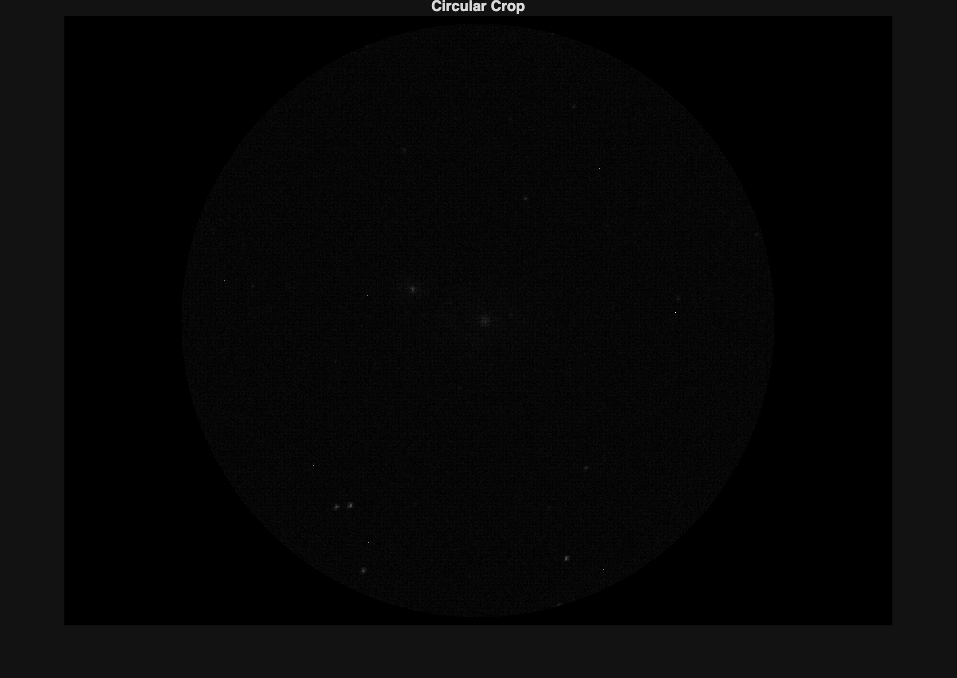

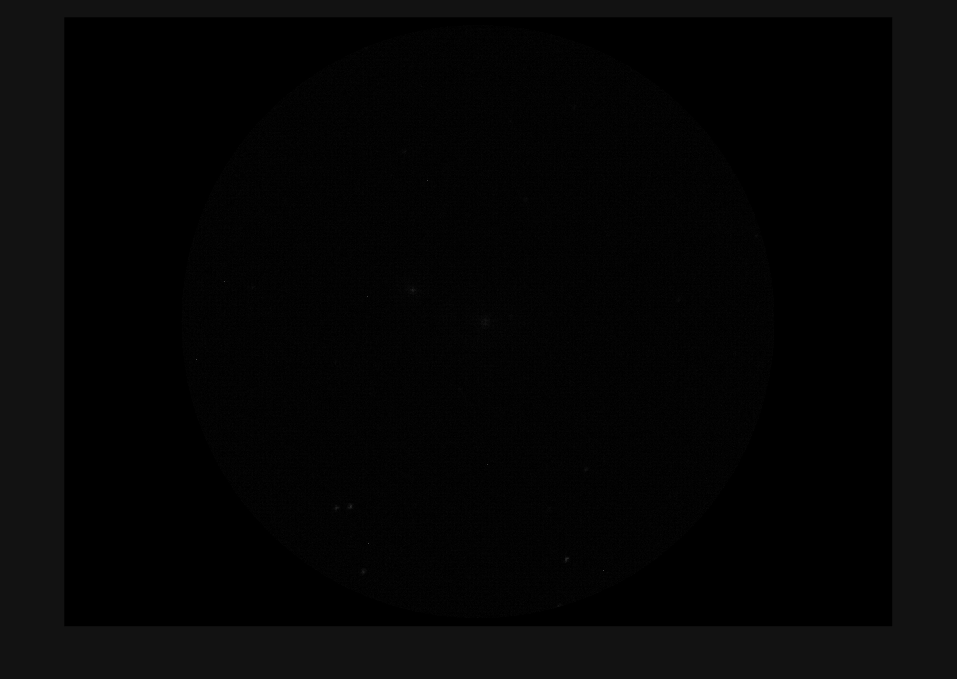

low_in = prctile(img_clean(:), .01);
high_in = prctile(img_clean(:), 99.95);
low_out = 0;
high_out = 1;
gamma = 2;
enhancedImg = imadjust(img_clean, [low_in high_in], [low_out high_out], gamma);

% 1. Create star mask (brightest pixels)
star_thresh = prctile(img_clean(:), 99.92);   % adjust to catch only brightest stars
star_mask = img_clean >= star_thresh;

% 2. Enhance bright stars
enhanced_stars = zeros(size(img_clean));
enhanced_stars(star_mask) = img_clean(star_mask);
% aggressive stretching only for stars
enhanced_stars(star_mask) = imadjust(enhanced_stars(star_mask), [star_thresh max(img_clean(:))], [0 1], 2);

% 3. Enhance faint background (excluding stars)
background = img_clean;
background(star_mask) = 0;  % remove stars
% mild stretching to make faint features visible
low_in_bg  = prctile(background(:), 0.01);
high_in_bg = prctile(background(:), 99.9995);
background = imadjust(background, [low_in_bg high_in_bg], [0 1], 1);

% 4. Recombine
combined = max(background, enhanced_stars);  % overlay stars on background



save_image(combined, "output/output.tif");